Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

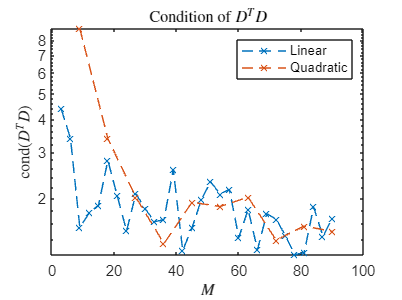

clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/example functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Sparse Grids MATLAB/")
addpath("c:/git/UQ4PDE_Homeworks/General functions/")


%generateMultiIndexSet(2, 1, 'HC')
%[coeff, indx, Dprod] = getLegendreCoefficientsND(@(x) f_gaussian(x), 1, 1, 'HC', 20)

%{
w = 1;
type = 'HC';
Mmax = 100;
Mstart = 20;
N = 2;
f = @(x) f_gaussian(x);
normplot = zeros(25, 1);
counter = 1;
tic
for m=Mstart:10:Mmax
    indxset = generateMultiIndexSet(N, w, type);
    [indxsize, ~] = size(indxset);
    
    y = rand([N m]);
    phi = zeros([m 1]);
    for i=1:m
        phi(i) = f(y(:, i));
    end
    
    D = ones(m, indxsize);
    for p=1:indxsize
        for i=1:m
            for n=1:N
                D(i, p) = D(i, p)*sqrt(2*indxset(p, n)+1)*legendreP(indxset(p, n), 2*y(n, i)-1);
            end
        end
    end
    Dtrans = transpose(D);
    Dprod = mtimes(Dtrans, D);
    normplot(counter) = norm(1/m*Dprod - eye(indxsize));
    counter = counter + 1;
end
toc

plot(20:10:100, normplot(1:9), 'x--')
title('Stability plot', 'Interpreter', 'latex')
xlabel('$M$', 'Interpreter', 'latex')
ylabel('$\|\frac{1}{M}cond(D^TD)-I\|$', 'Interpreter', 'latex')
savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'normCond_N2_w1')
%}

%{
wmax = 10
type = 'HC';
N = 2;
f = @(x) f_gaussian(x);
condition = zeros(wmax, 1);
tic
for w=progress(1:wmax)
    [Mindx, ~] = size(generateMultiIndexSet(N, w, type));
    M = 30;
    [coeff, indxset, DTD] = getLegendreCoefficientsND(f, w, N, type, M);
    condition(w) = cond(DTD);
end
toc

figure()
semilogy(1:wmax, condition, 'x--')
title('Condition of $D^TD$', 'Interpreter', 'latex')
xlabel('$w$', 'Interpreter', 'latex')
ylabel('cond$(D^TD)$', 'Interpreter', 'latex')
%}


x = linspace(0, 1, 100);
w = 1;
N = 2;
type = 'HC';
cmax = 5;
f = @(x) f_gaussian(x);
tic
[Mindx, ~] = size(generateMultiIndexSet(N, w, type));
for i=1:2
    if i==1
        cmax = 30;
        stringplot = 'Linear';
    else
        cmax = 10;
        stringplot = 'Quadratic';
    end
    condition = zeros(cmax, 1);
    M = zeros(cmax, 1);
    for c=progress(1:cmax)
        M(c) = c*Mindx^i;
        [coeff, indxset, DTD] = getLegendreCoefficientsND(f, w, N, type, M(c));
        condition(c) = cond(DTD);
    end
    semilogy(M, condition, 'x--')
    title('Condition of $D^TD$', 'Interpreter', 'latex')
    xlabel('$M$', 'Interpreter', 'latex')
    ylabel('cond$(D^TD)$', 'Interpreter', 'latex')
    legend('Linear', 'Quadratic')
    hold on;
    savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'Cond(DTD)vsM_w1_N2_HC')
end

toc

Elapsed time is 223.653748 seconds.
